# Estimate Bit Error Rate for 16-QAM OFDM in AWGN and LTI channel

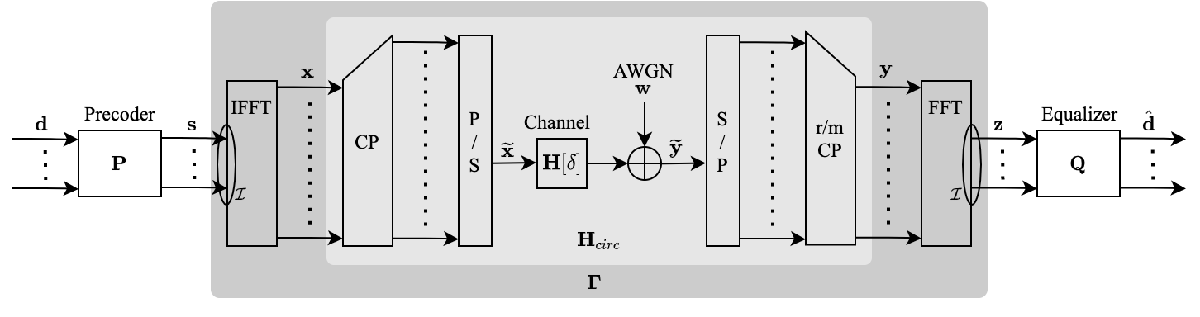

CLEAN_RUN = false;

if CLEAN_RUN
    clear; clc; clf; %#ok<UNRCH>
end

DEBUG = false;

Simulation parameters.

SCHEME = "SC-FDMA";
EQUALIZER = "MMSE";

M = 16;                 % 16-QAM
k = log2(M);            % Bits per symbol

fft_size = 128;         % FFT size
cp_length = 9;          % Cyclic prefix length

mod_symbol_size = 48;   % Modulation symbol size
subcarrier_idx = (41:88);

N_block = 1e3;          % Number of blocks(OFDM symbols)
N_trial = 1e3;          % Number of Monte Carlo trials

EbNo = (0:5:30);            % Eb/No(dB)
SNR = EbNo + 10*log10(k);   % Convert Eb/No to SNR(dB)

Block functions.

% Precoder
if strcmp(SCHEME, 'OFDMA')
    P = eye(mod_symbol_size);
else
    P = (1/sqrt(mod_symbol_size)) * dftmtx(mod_symbol_size);
end

% Add CP
% Same as
% cp = ifft_data(end-cp_length+1: end);
% cp_data = [cp; ifft_data];
CP_matrix = [zeros(cp_length, fft_size-cp_length) eye(cp_length); eye(fft_size)];

% Remove CP
% Same as
% rx_rm_cp = rx_parallel(cp_length+1: end);
rm_CP_matrix = [zeros(fft_size, cp_length) eye(fft_size)];

% Subcarier mapping
sub_map_matrix = [zeros( subcarrier_idx(1)-1, mod_symbol_size ); eye(mod_symbol_size); zeros( fft_size-subcarrier_idx(end), mod_symbol_size )];

% Subcarier demapping
sub_demap_matrix = transpose(sub_map_matrix);

Channel.

% Power delay profile
h_dB = [0 -Inf -Inf -3 -Inf -Inf -Inf -Inf -Inf -5];

% Channel impulse response
h = db2mag(h_dB)';

% Channel frequency response
H_k = fft(h, fft_size); % no normalization

% Circulant matrix
% H_circ = circulant_matrix(h, fft_size+cp_length);  % == T

Gamma = diag(H_k);

if DEBUG
    figure   %#ok<UNRCH>
    stem(h)
    set(gca, 'yscale', 'log');
    xlim([0, 11]); ylim([0.5, 1.1]);
end

Equalizers.

% Zero-forcing equalizer
Q_ZF_all_sub = diag(1./H_k);
Q_ZF = Q_ZF_all_sub(subcarrier_idx, subcarrier_idx);

% least-squares equalizer
% Q_ls = (H_low' * H_low)\H_low';

Monte Carlo simulation.

% BER estimation
ber_est = zeros(size(EbNo));

tic

parfor n = 1:length(EbNo)
    % Reset the error bit counter
    numErrs = 0;
    
    % MMSE equalizer
    MMSE_snr = k * db2mag(SNR(n));
    Q_MMSE_all_sub = diag( (MMSE_snr*conj(H_k) ) ./ ( 1 + MMSE_snr*(abs(H_k).^2) ));
    Q_MMSE = Q_MMSE_all_sub(subcarrier_idx, subcarrier_idx);
    
    for trial_idx = 1:N_trial
        % ---------- Tx ----------
        % Generate binary data and convert it to decimal symbols
        bin_data = randi([0, 1], k, mod_symbol_size * N_block)';
        dec_data = bi2de(bin_data, 'left-msb');
        
        % QAM mapping and normalize the symbol energy
        mod_symbol_data_stream = qammod(dec_data, M, 'UnitAveragePower', true);
        mod_symbol_data_block = reshape(mod_symbol_data_stream, mod_symbol_size, N_block);
        
        % Debug. Plot constellation:
        if DEBUG && (n == 5) && (trial_idx == 1)
            scatterplot(mod_symbol_data_stream), grid;
            title('Constellation');
        end
        
        % Precoder
        precode_data = P * mod_symbol_data_block;
        
        % Subcarrier mapping
        subcarrier_map_data = sub_map_matrix * precode_data;
        
        % IFFT
        % sqrt(fft_size) for normalizing the power of transmit symbol to 1
        ifft_data = (sqrt(fft_size)) * ifft(subcarrier_map_data);
        
        % Cyclic prefix
        cp_data = CP_matrix * ifft_data;
        
        % Parallel to serial
        txSig = reshape(cp_data, 1, []);
        
        % ------- Channel --------
        channel_out = conv(txSig, h);
        
        % Remove the part of the signal that was spread by the channel
        channel_out_rm_spread = channel_out(1: end-length(h)+1);
        
        % AWGN noise
        rxSig = awgn(channel_out_rm_spread, SNR(n));
        
        %% Same as rxSig = awgn(channel_out_rm_spread, SNR(n))
        % noise = 1/sqrt(2)*(randn(1,length(txSig)) + 1i*randn(1,length(txSig))); % white guassian noise, 0dB variance
        % rxSig = txSig + 10^(-snr/20)*noise; % additive white gaussian noise
        
        % ---------- Rx ----------
        %Serial to parallel
        rx_parallel = reshape(rxSig, fft_size+cp_length, N_block);
        
        % Remove cyclic prefix
        rx_rm_cp = rm_CP_matrix * rx_parallel;
        
        % FFT
        % 1/sqrt(fft_size) for normalizing the power of transmit symbol to 1
        rx_fft = (1/sqrt(fft_size)) * fft(rx_rm_cp);
        
        % Subcarrier demapping
        rx_subcarrier_demap = sub_demap_matrix * rx_fft;
        
        % Equalizer
        if strcmp(EQUALIZER, 'ZF')
            Q = Q_ZF;
        else
            Q = Q_MMSE;
        end
        if strcmp(SCHEME, 'SC-FDMA')
            % IDFT
            Q = sqrt(mod_symbol_size) * ifft(Q);
        end
        eq_out = Q * rx_subcarrier_demap;
        
        
        % Debug. Plot constellation:
        if DEBUG && (n == 5) && (trial_idx == 1)
            scatterplot(reshape(eq_out, [], 1)), grid;
            xlim([-1, 1]); ylim([-1, 1]);
            title('Constellation');
        end
        
        % QAM demodulate
        rx_dec_data = qamdemod(eq_out, M, 'UnitAveragePower', true);
        rx_bin_data = de2bi(rx_dec_data, k, 'left-msb');
        
        % Calculate the number of bit errors
        nErrors = biterr(bin_data, rx_bin_data);
        
        % Increment the error counter
        numErrs = numErrs + nErrors;
    end
    
    % Estimate the BER
    ber_est(n) = numErrs/(N_block*N_trial*mod_symbol_size*k);
end

toc

Elapsed time is 60.591479 seconds.


Theoretical BER.


$$P_{b, 16QAM} = \frac{3}{2k}{erfc}\left(\sqrt{\frac{k E_{b}}{10 N_{0}}}\right)$$


berTheory_awgn = berawgn(EbNo, 'qam', M);

%% Same as berawgn(EbNo, 'qam', M)
% berTheory = (1/k)*3/2*erfc(sqrt(k*0.1*(10.^(EbNo/10))));

%% berTheory for fading channel?
% berTheory_fading = berfading(EbNo, 'qam', M, length(c_dB)-1);

Plot estimated and theoretical BER.

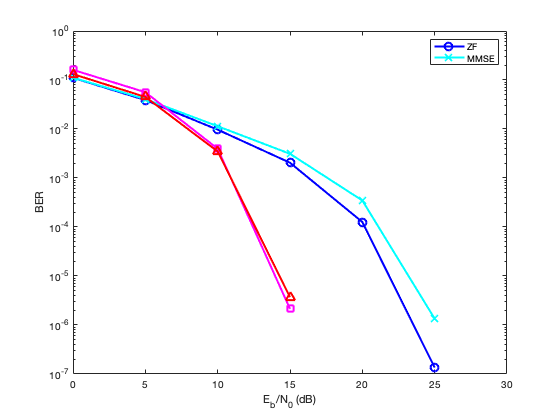

semilogy(EbNo, ber_OFDMA_ZF, 'Marker', 'o', 'Color', 'b', 'LineWidth', 2, 'MarkerSize', 8);
hold on;
semilogy(EbNo, ber_OFDMA_MMSE, 'Marker', 'x', 'Color', 'c', 'LineWidth', 2, 'MarkerSize', 8);
semilogy(EbNo, ber_SC_FDMA_ZF, 'Marker', 's', 'Color', 'm', 'LineWidth', 2, 'MarkerSize', 8);
semilogy(EbNo, ber_SC_FDMA_MMSE, 'Marker', '^', 'Color', 'r', 'LineWidth', 2, 'MarkerSize', 8);

% semilogy(EbNo, ber_est, '*');
% semilogy(EbNo, berTheory_awgn);
grid;
% legend('Estimated BER','Theoretical BER');

legend('OFDMA ZF', 'OFDMA MMSE', 'SC-FDMA ZF', 'SC-FDMA MMSE');
ylabel('BER');
xlim([0, 30]); % ylim([1e-4, 1e0]);
xlabel('E_b/N_0 (dB)');